# MATLAB Documentation / Help

help

New to MATLAB? See resources for Getting Started.

To view the documentation, open the Help browser.



help sin

 sin    Sine of argument in radians.
    sin(X) is the sine of the elements of X.
 
    See also asin, sind, sinpi.

    Documentation for sin



% doc sin

help plot

 plot   Linear plot. 
    plot(X,Y) plots vector Y versus vector X. If X or Y is a matrix,
    then the vector is plotted versus the rows or columns of the matrix,
    whichever line up.  If X is a scalar and Y is a vector, disconnected
    line objects are created and plotted as discrete points vertically at
    X.
 
    plot(Y) plots the columns of Y versus their index.
    If Y is complex, plot(Y) is equivalent to plot(real(Y),imag(Y)).
    In all other uses of plot, the imaginary part is ignored.
 
    Various line types, plot symbols and colors may be obtained with
    plot(X,Y,S) where S is a character string made from one element
    from any or all the following 3 columns:
 
           b     blue          .     point              -     solid
           g     green         o     circle             :     dotted
           r     red           x     x-mark         

help size

 size   Size of array.  
    D = size(X), for M-by-N matrix X, returns the two-element row vector
    D = [M,N] containing the number of rows and columns in the matrix.
    For N-D arrays, size(X) returns a 1-by-N vector of dimension lengths.
    Trailing singleton dimensions are ignored.
 
    [M,N] = size(X) for matrix X, returns the number of rows and columns in
    X as separate output variables. 
    
    [M1,M2,M3,...,MN] = size(X) for N>1 returns the sizes of the first N 
    dimensions of the array X.  If the number of output arguments N does
    not equal NDIMS(X), then for:
 
    N > NDIMS(X), size returns ones in the "extra" variables, i.e., outputs
                  NDIMS(X)+1 through N.
    N < NDIMS(X), MN contains the product of the sizes of dimensions N
                  through NDIMS(X).
 
    M = size(X,DIM) returns the lengths of the specified dimens

# Commands

% clear
% clear workspace
% clear classes

# Vectors & Matrices

x = [5 , 9]

x =      5     9


x = [5;9]

x =      5
     9


x= [1,3,5;2,4,6]

x =      1     3     5
     2     4     6


## Evenly-Spaced Vectors

x= 1:4

x =      1     2     3     4



% [start : step : end]: e.g. 1 to 10 with step 2 would be:
% (whereas in Python step would be at the end)
x =[1 : 2 : 10]

x =      1     3     5     7     9




% if you know the number of elements you want in a vector beforehand 
% use linspace(first,la1,1st,number_of_elements)
x = linspace(0,10,5)

x =          0    2.5000    5.0000    7.5000   10.0000



% use transpose to turn it into a column vector of 5x1:
x_transpose = x'

x_transpose =          0
    2.5000
    5.0000
    7.5000
   10.0000



% create a column vector using a single command by creating a row vector 
% and then transpose it all on one line:
x = (4:2:10)'

x =      4
     6
     8
    10


# Visualization - Plotting

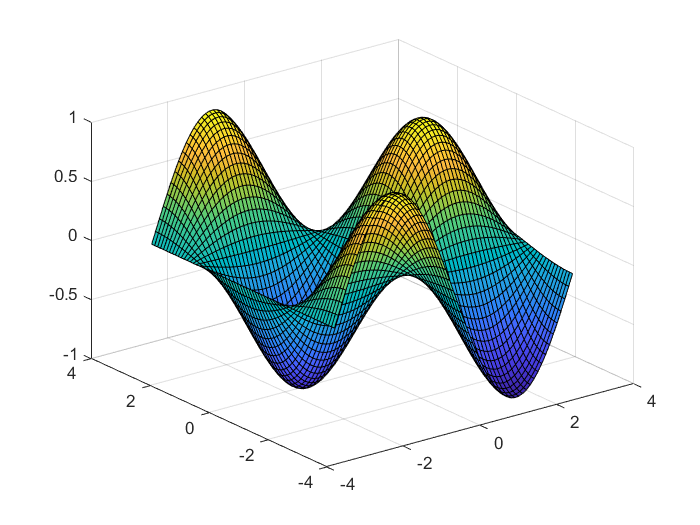

x = -pi : 0.1 : pi;
y = -pi : 0.1 : pi;
[X,Y] = meshgrid(x,y);

Z = sin(X) .*cos(Y);

% plot
surf(X,Y,Z);

# Programming Constructs

% find()

x = rand (1, 10);
x

x =     0.9294    0.7757    0.4868    0.4359    0.4468    0.3063    0.5085    0.5108    0.8176    0.7948



indices = find(x>0.2 & x<0.6)

indices =      3     4     5     6     7     8


## Data Structures

% create a struct
myStruct = struct('Name', {'Mary', 'Leo', 'John'}, ...
    "Age", {27,35, 40})

myStruct = 1×3 struct array with fields:
    Name
    Age


    
% view the 1st row
myStruct(1)

ans = struct with fields:
    Name: 'Mary'
     Age: 27



% view specific column value of that row
myStruct(1).Age 

ans = 27


% view column values of "Name"
myStruct.Name

ans = 'Mary'

ans = 'Leo'

ans = 'John'